STATE SPACE MODEL SIMUL.ATION

1.

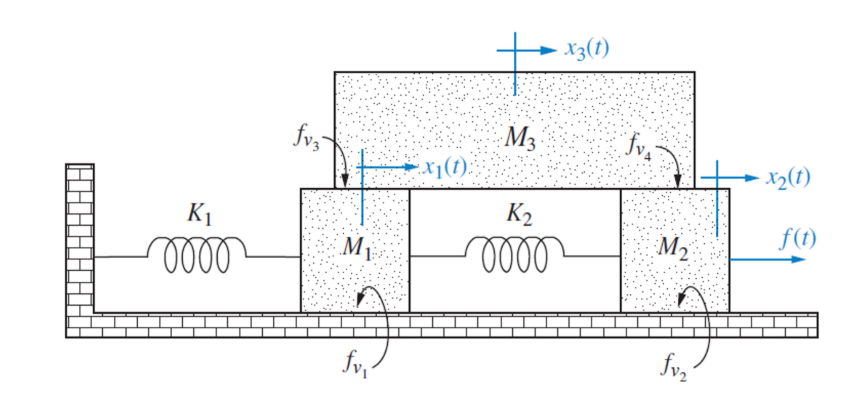

clear all;
close all;
clc;

F = 1;
K1 = 1;
K2 = 1;
M1 = 1;

Sim_Time = 25;

A = [0 1 0 0 0 0;
    -2 -2 1 0 0 1;
     0 0 0 1 0 0;
     1 0 -1 -2 0 1;
     0 0 0 0 0 1;
     0 1 0 1 0 -2];

B = [0;
    0;
    0;
    1;
    0;
    0];

C = [1 0 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 0 1 0];

D = [0;
    0;
    0];

ssp_No1 = ss(A,B,C,D)


ssp_No1 =
 
  A = 
       x1  x2  x3  x4  x5  x6
   x1   0   1   0   0   0   0
   x2  -2  -2   1   0   0   1
   x3   0   0   0   1   0   0
   x4   1   0  -1  -2   0   1
   x5   0   0   0   0   0   1
   x6   0   1   0   1   0  -2
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
   x5   0
   x6   0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   0   1   0   0   0
   y3   0   0   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.


tf(ssp_No1)


ans =
 
  From input to output...
                       2 s + 2
   1:  ---------------------------------------
       s^5 + 6 s^4 + 13 s^3 + 16 s^2 + 8 s + 2
 
                s^3 + 4 s^2 + 5 s + 4
   2:  ---------------------------------------
       s^5 + 6 s^4 + 13 s^3 + 16 s^2 + 8 s + 2
 
              s^3 + 2 s^2 + 3 s - 3.281e-16
   3:  -------------------------------------------
       s^6 + 6 s^5 + 13 s^4 + 16 s^3 + 8 s^2 + 2 s
 
Continuous-time transfer function.


sim('ss_Laboratory4no1.slx');

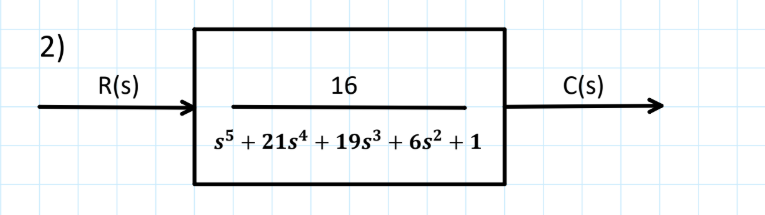

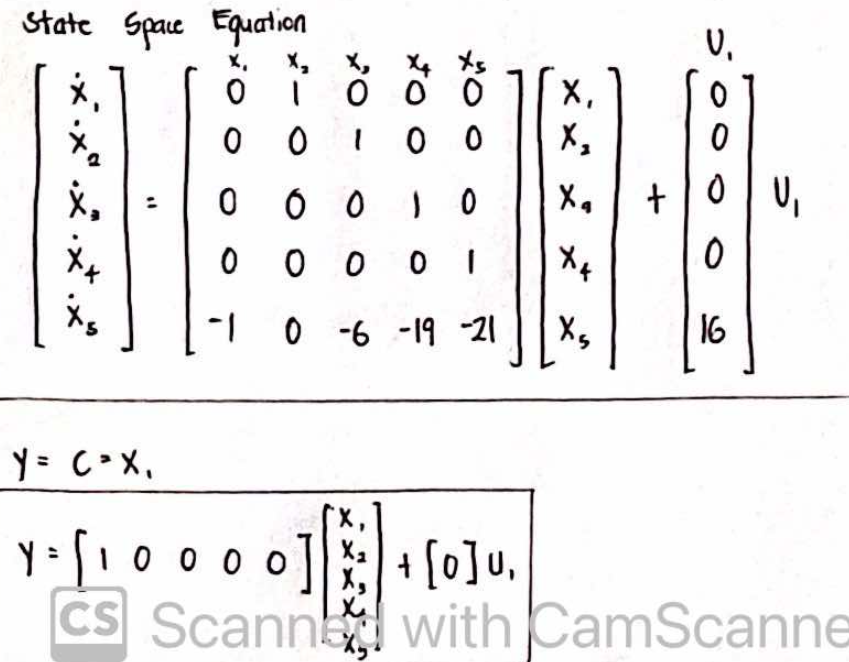

clear all;
close all;
clc;

F = 1;
Sim_Time = 25;

A = [0 1 0 0 0;
     0 0 1 0 0;
     0 0 0 1 0;
     0 0 0 0 1;
    -1 0 -6 -19 -21];

B = [0;
    0;
    0;
    0;
    16];

C = [1 0 0 0 0];

D = [0];

ssp_No2 = ss(A,B,C,D)


ssp_No2 =
 
  A = 
        x1   x2   x3   x4   x5
   x1    0    1    0    0    0
   x2    0    0    1    0    0
   x3    0    0    0    1    0
   x4    0    0    0    0    1
   x5   -1    0   -6  -19  -21
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
   x5  16
 
  C = 
       x1  x2  x3  x4  x5
   y1   1   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


tf(ssp_No2)


ans =
 
                        16
  -----------------------------------------------
  s^5 + 21 s^4 + 19 s^3 + 6 s^2 - 4.441e-15 s + 1
 
Continuous-time transfer function.
Model Properties


sim('ss_Laboratory4no2.slx');

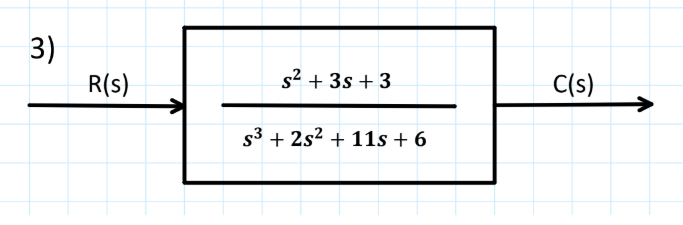

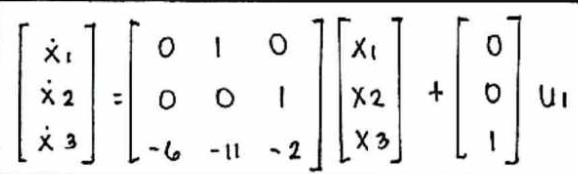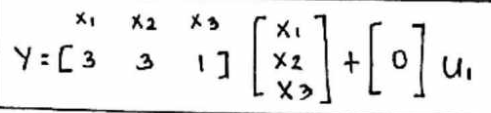

clear all;
close all;
clc;

F = 1;
Sim_Time = 25;

A = [0 1 0 ;
     0 0 1 ;
    -6 -11 -2];

B = [0;
     0;
     1];

C = [3 3 1];

D = [0];

ssp_No3 = ss(A,B,C,D)


ssp_No3 =
 
  A = 
        x1   x2   x3
   x1    0    1    0
   x2    0    0    1
   x3   -6  -11   -2
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   3   3   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


tf(ssp_No3)


ans =
 
      s^2 + 3 s + 3
  ----------------------
  s^3 + 2 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


sim('ss_Laboratory4no3.slx');